# **LI-DTI: Linear Interpretable Drug-Target Interaction **

**Drug Cold Start Scenario**

- Output: Calculate and plot of the AUC and AUPR (mean,std) using the AUC and AUPR functions.

## Initialization 

clear all;

Load predictions for every method

load('../repository/cold_start_evaluation_1/drug_cold_start/DTINet/DTInet_10CV_predictions_10_to_1.mat');
load('../repository/cold_start_evaluation_1/drug_cold_start/KGE_NFM/KGE_NFM_10_cv_predictions.mat');
load('../repository/cold_start_evaluation_1/drug_cold_start/neoDTI/neoDTI_10_cv_predictions.mat');
load('../repository/cold_start_evaluation_1/drug_cold_start/our_method/our_method_predictions_10CV_2026.mat');
load('../repository/cold_start_evaluation_1/drug_cold_start/hampDTI/hampDTI_predictions.mat');

pred = {our_method_predictions,...
    neoDTI_predictions,...
    DTINet_predictions_10_1,...
    KGE_NFM_predictions,...
    hampDTI_predictions};

Load DTI matrix

R = load('../data/luo_dataset/mat_drug_protein.txt');

Similarities for initialisation

indexProt = sum(R,1) > 0;   
indexDrug = sum(R,2) > 0;
R = R(indexDrug,indexProt);
top_N_list = [1 5 10 20 50 100];
nfolds = 10;
n_methods = length(pred);
method_names = {'Our Method','NeoDTI','DTINet','KGE NFM','hampDTI'};

Calculate AUC and AUPR for the methods

metric_func1 = @AUC;
metric_func2 = @AUPR;
for method = 1:n_methods
    AUC_CV = zeros(nfolds,1);
    AUPR_CV = zeros(nfolds,1);
    for cv = 1:nfolds
        AUC_split = zeros(nfolds,1);
        AUPR_split = zeros(nfolds,1);
        for split = 1:nfolds
            load(['../data/luo_dataset/drug_cold_start/our_method/cv_' int2str(cv) '/test' int2str(split)]);
            labels = test_fold(:,3);
            indx = sub2ind(size(R),test_fold(:,1),test_fold(:,2));
            scores = pred{method}{cv}{split}(indx);
            AUC_split(split) = AUC(labels,scores);
            AUPR_split(split) = AUPR(labels,scores);
        end
        AUC_CV(cv) = mean(AUC_split);
        AUPR_CV(cv) = mean(AUPR_split);
    end
    AUC_row{method} = AUC_CV;
    AUPR_row{method} = AUPR_CV;
end

for i = 1:n_methods
 AUC_plot(:,i) = AUC_row{i};
 AUPR_plot(:,i) = AUPR_row{i};
end

wAUC = AUC_plot;
wAUPR = AUPR_plot;

% Can be saved the matrices for plotting in python the results
%save("../../repository/paper_data/drug_CS_AUC.mat",'wAUC');
%save("../../repository/paper_data/drug_CS_AUPR.mat",'wAUPR');

Plot the AUC and AUPR for the drug cold start evaluation

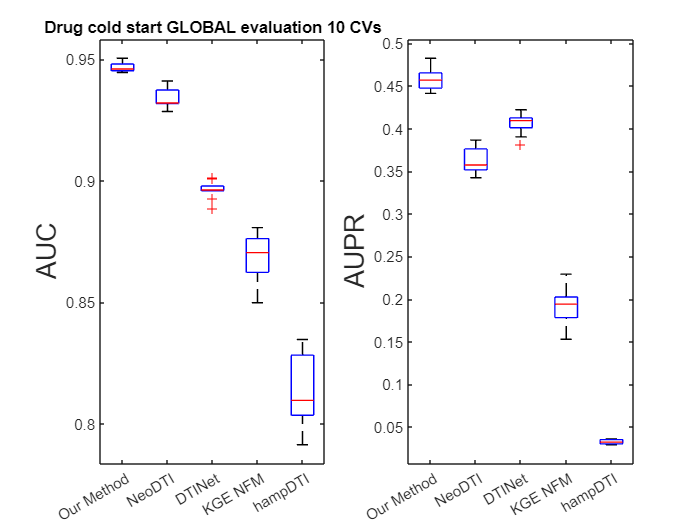

figure;
subplot(1,2,1);
boxplot(AUC_plot);
ylabel('AUC', 'FontSize', 16);
set(gca,'xticklabel',method_names);
title('Drug cold start GLOBAL evaluation 10 CVs');
%set(gca,'YTick',0.84:0.02:1);
% ylim([0.84 1]);

subplot(1,2,2);
boxplot(AUPR_plot);
%xlabel('Unalanced', 'FontSize', 16);
ylabel('AUPR', 'FontSize', 16);
set(gca,'xticklabel',method_names);